Copyright © 2021  Shababuddin Khan  || sk@pcampus.edu.np

*Department of Electrical Engineering, *[Pulchowk Campus](https://pcampus.edu.np/)*, Tribhuwan University, Nepal*

A Series of  Module has been designed and developed by author mentioned above with full copyright for a course of **Control System** to demonstrante the concept of control system and its implementation in real life to second year Aerospace engineering students at Tribhuwan University.

# ***MODULE VI: Root Locus***

**Root Locus is defined **as, the locus of the closed loop poles obtained when system gain 'K' is varied from -∞ to +∞ is called Root Locus. When 'K' is varied from 0 to +∞, the plot is called **Direct root locus.**

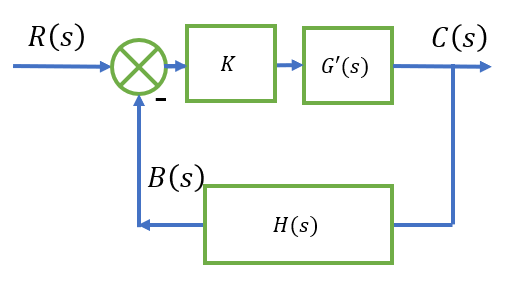

Fig: Variation of Roots due to Gain

# 6.1 Construction of Root Locus by Manual Way

## 6.1.1 Root Locus for One Simple Open Loop Poles

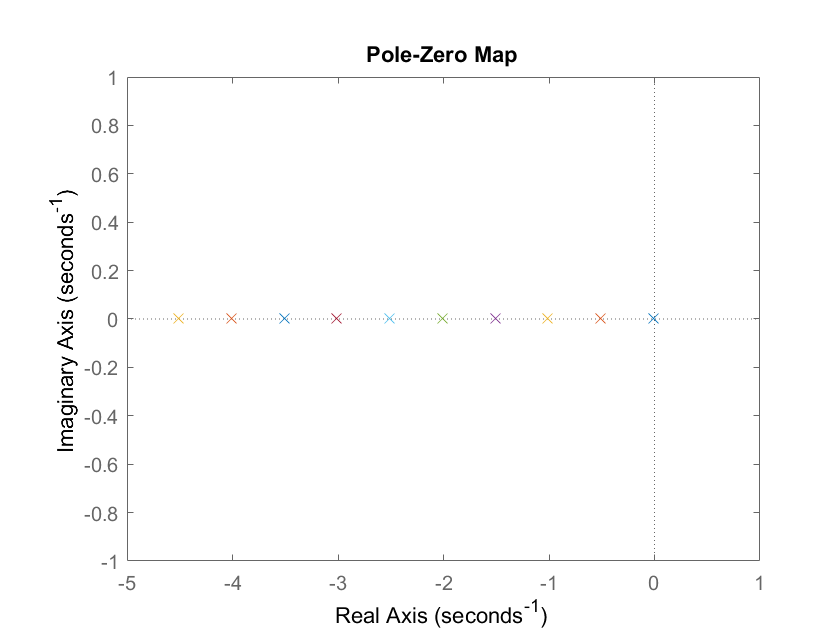

s=tf('s');
H=1;
figure;

hold on
for K=0.01:0.5:20
G=K/(s);
CLG=feedback(G,H);      % This is to create a closed loop TF
pzplot(CLG);            %Plot of CLosed Loop TF
xlim([-5 1]);
end
hold off

% rlocus(G);              %In rlocus you give Open Loop TF i.e GH

## 6.1.2 Root Locus for Two Simple Open Loop Poles

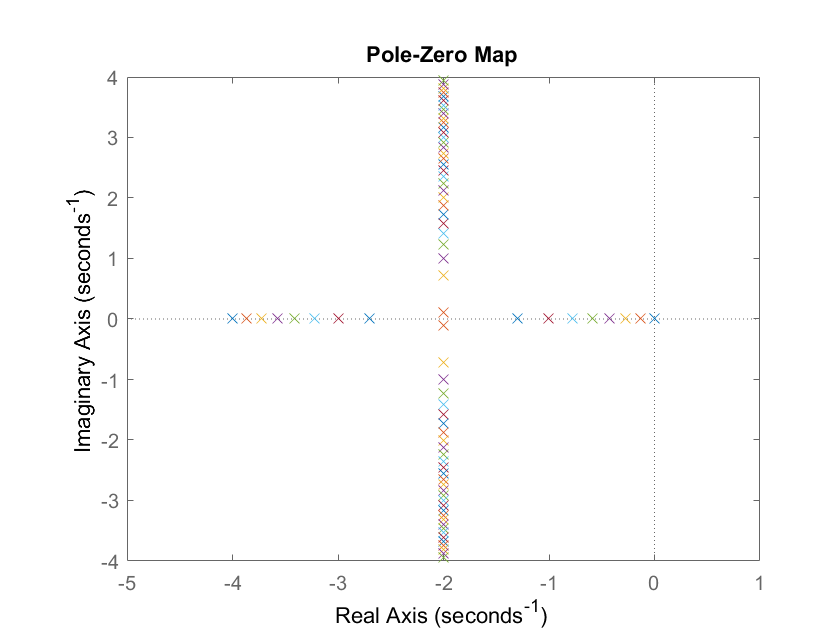

s=tf('s');
H=1;
figure;

hold on
for K=0.01:0.5:20
G=K/(s*(s+4));
CLG=feedback(G,H);
pzplot(CLG);
xlim([-5 1]);
end
hold off

% rlocus(G);

## 6.1.3 Root Locus for Two Simple Open Loop Poles and a Zeros

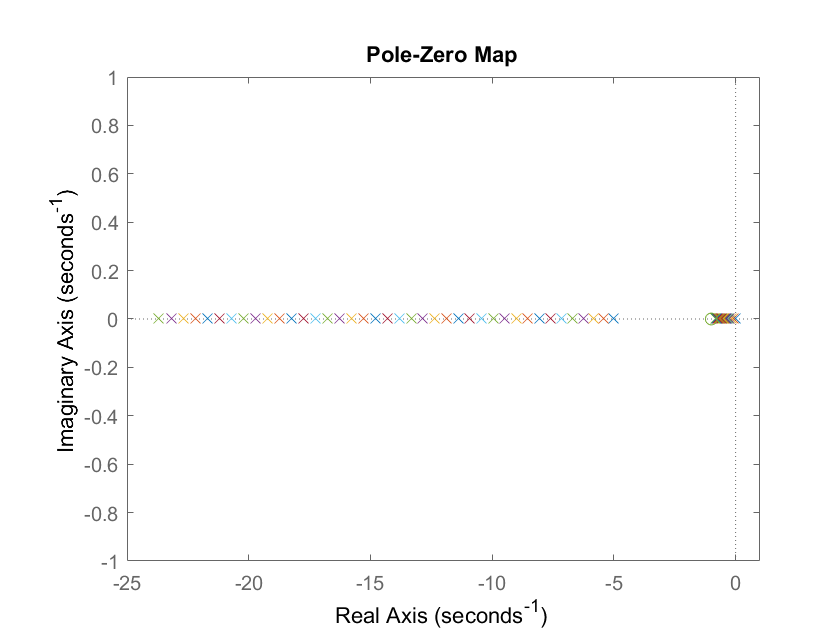

s=tf('s');
H=1;
figure;

hold on
for K=0.01:0.5:20
G=K*(s+1)/(s*(s+5));
CLG=feedback(G,H);          
pzplot(CLG);                
xlim([-25 1]);
end
hold off

% rlocus(G);      

# 6.2 Relation Between Root Locus and Time Response of System

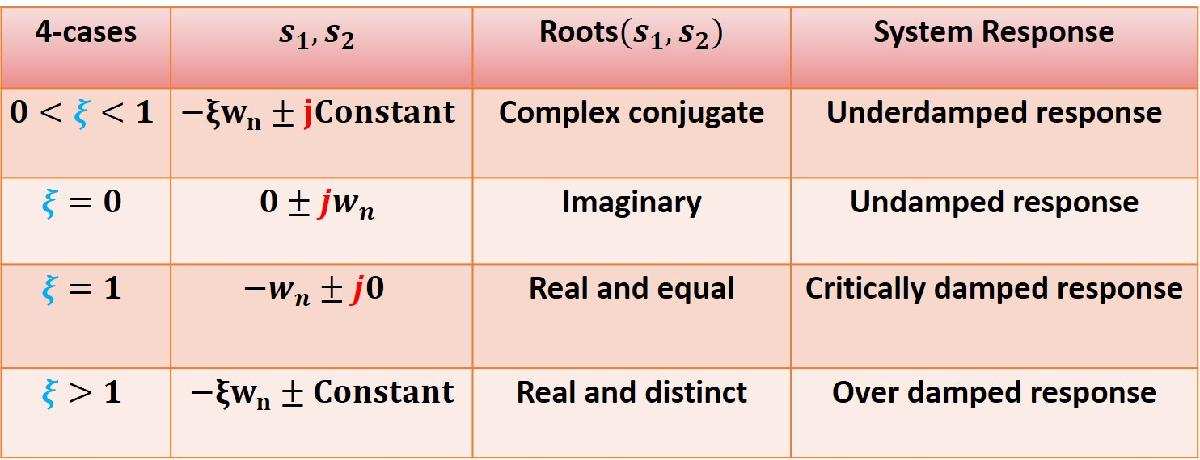

## 6.2.1 Variation of Gain by Slider

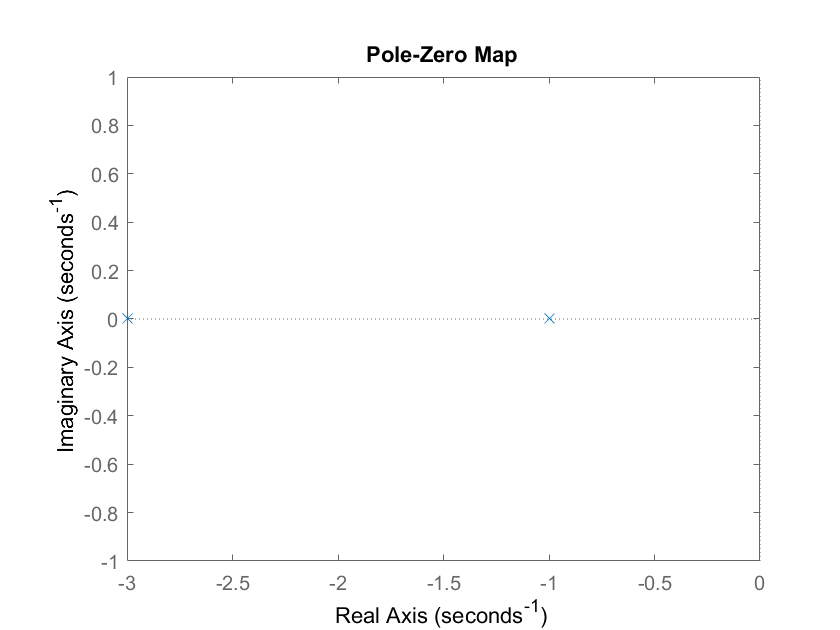

s=tf('s');
H=1;
figure;
K=3;   % Variation of Gain
G=K/(s*(s+4));
CLG=feedback(G,H);
pzmap(CLG);

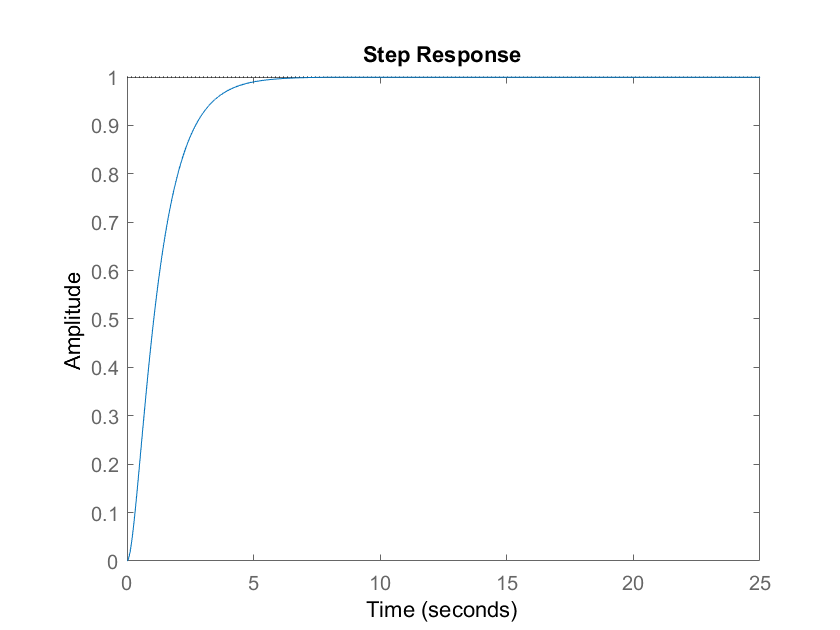

step(CLG);                % Plot Step response of closed loop system
xlim([0,25]);

## 6.2.2 Variation of Gain by Loop

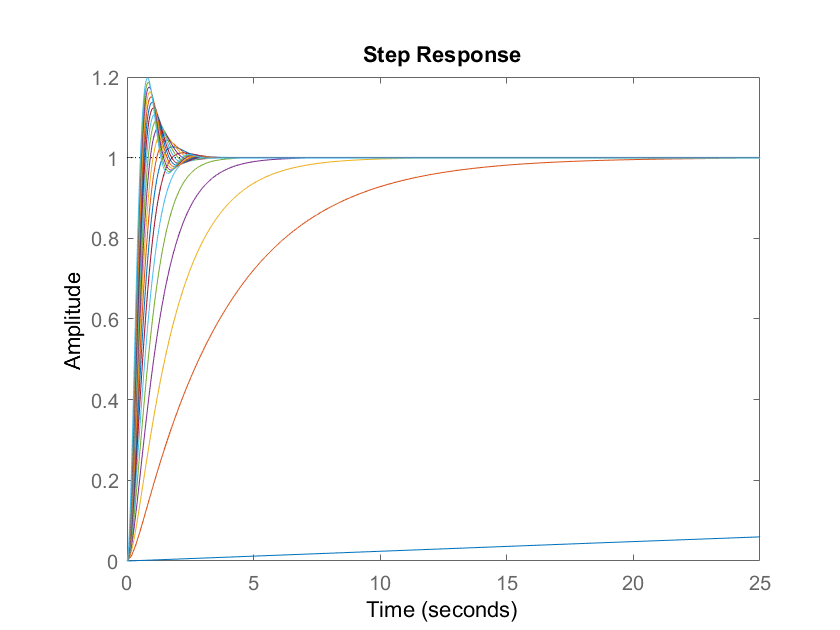


s=tf('s');
H=1;
figure;

hold on
for K=0.01:1:20   % Variation of Gain
G=K/(s*(s+4));
CLG=feedback(G,H);
step(CLG);                % Plot Step response of closed loop system
xlim([0,25]);
%legend(K);
end
hold off

## 6.2.3 Variation of Gain by Defining Variable

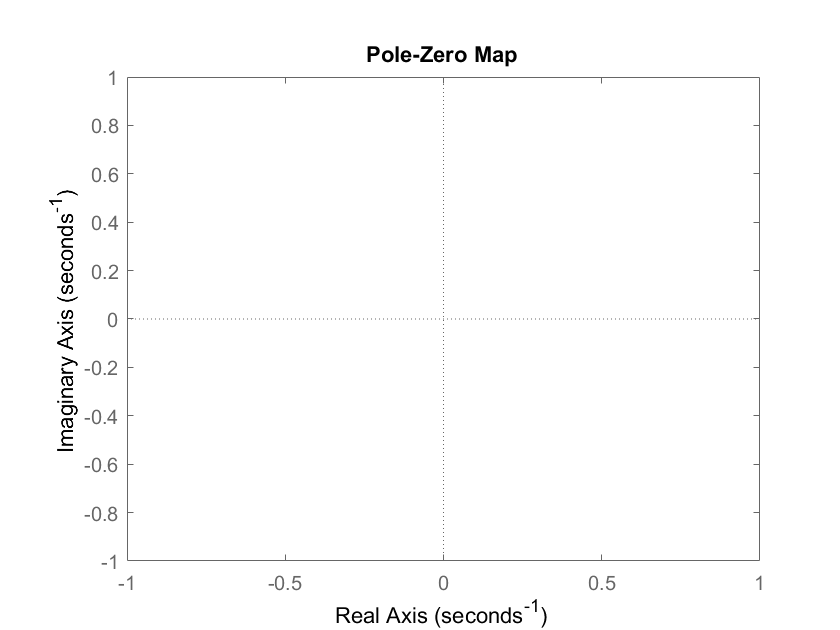

clear
s=tf('s');
K=0;
G=K/(s*(s+4));
pzplot(G)

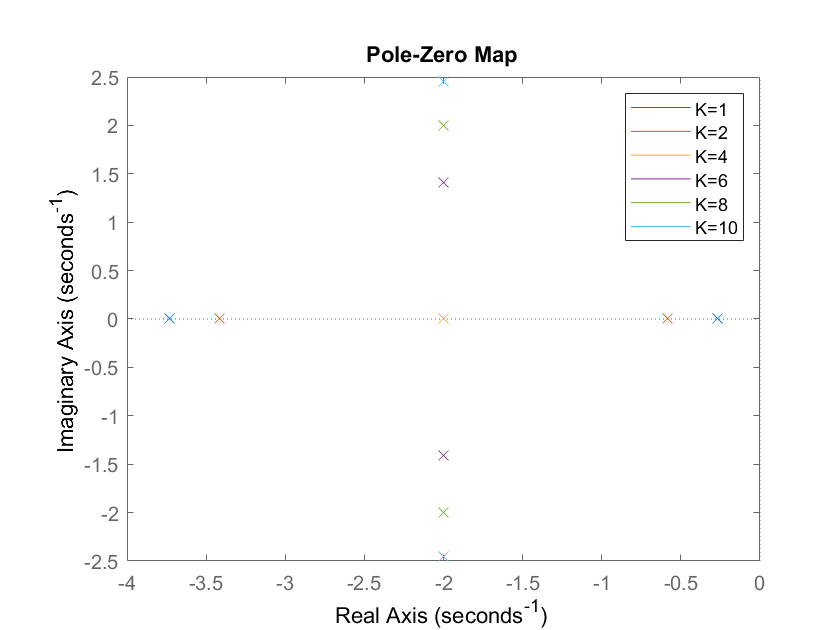

K=1;
G1=K/(s*(s+4));
K=2;
G2=K/(s*(s+4));
K=4;
G3=K/(s*(s+4));
K=5;
G4=K/(s*(s+4));
K=6;
G5=K/(s*(s+4));
K=8;
G6=K/(s*(s+4));
K=10;
G7=K/(s*(s+4));
H=1;
T1=feedback(G1,H);

T2=feedback(G2,H);

T3=feedback(G3,H);

T4=feedback(G4,H);

T5=feedback(G5,H);

T6=feedback(G6,H);

T7=feedback(G7,H);


pzmap(T1,T2,T3,T5,T6,T7);
legend K=1 K=2 K=4 K=6 K=8 K=10

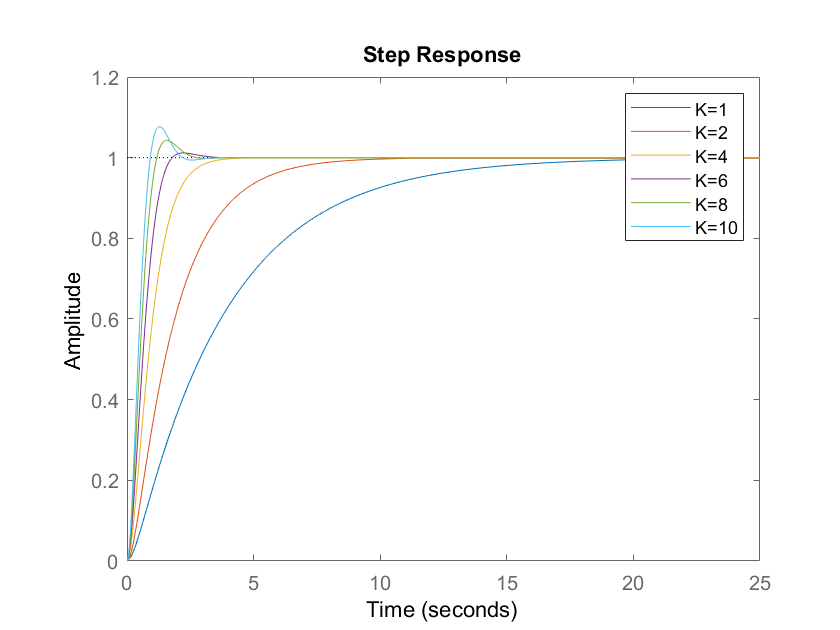

step(T1,T2,T3,T5,T6,T7);
legend K=1 K=2 K=4 K=6 K=8 K=10

%rlocus(G1)

# 6.3 Sketching Root Locus by Matlab

It can be acieved by using rlocus() command.

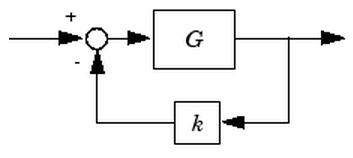

Fig: System in Matlab for rlocus()

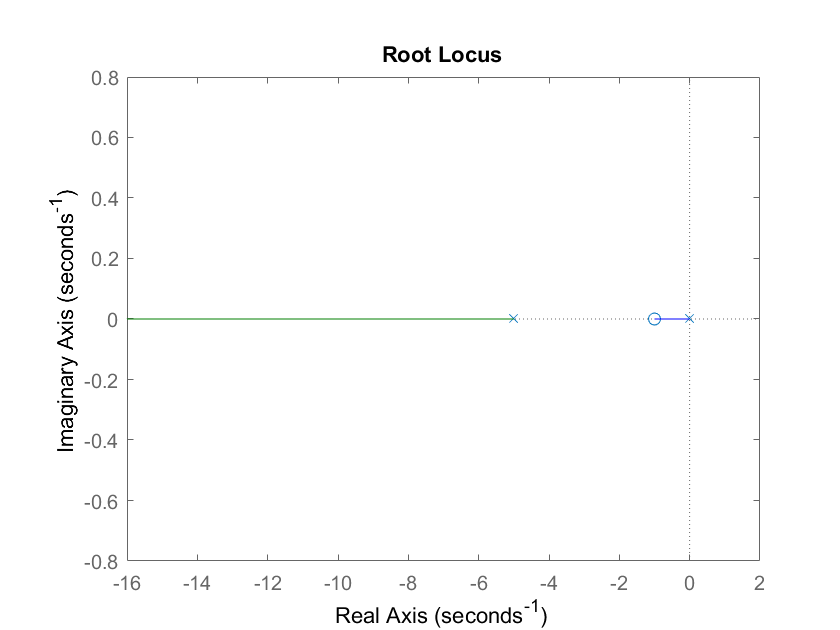

G=K*(s+1)/(s*(s+5));  % Open Loop Gain
H=1;
GH=G*H;
rlocus(GH)  %rlocus() uses open loop transfer function to plot.

% Lets Plot some System
s=tf('s');
G1=1/(s*(s+4)*(s+5));
G2=(s+2)/(s^2+2*s+3);
G3=(s+1)/(s*(s-1));
G4=(s+1)/((s^2+2*s+5)*(s^2+2*s+2));


G4 =
 
               s + 1
  --------------------------------
  s^4 + 4 s^3 + 11 s^2 + 14 s + 10
 
Continuous-time transfer function.



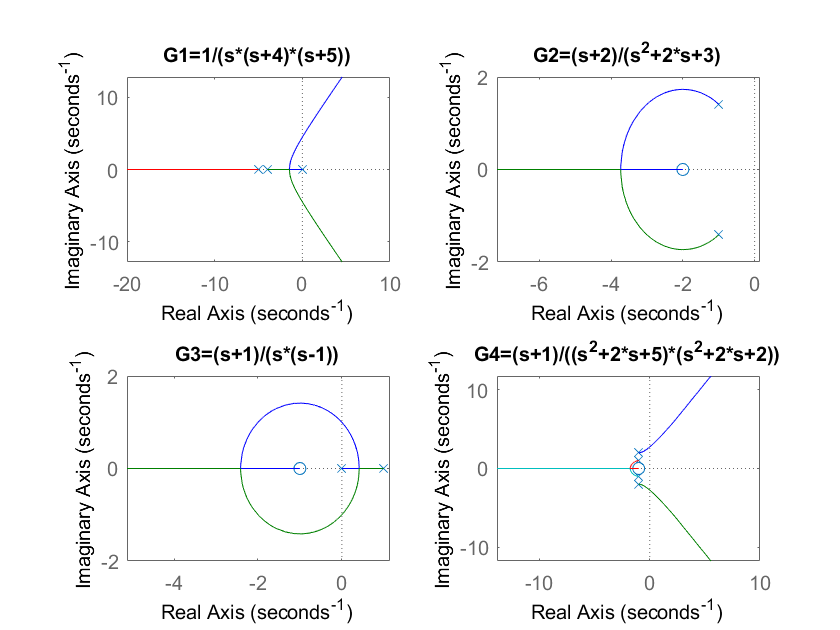

figure
subplot(2,2,1);
rlocus(G1);
title('G1=1/(s*(s+4)*(s+5))')
subplot(2,2,2);
rlocus(G2);
title('G2=(s+2)/(s^2+2*s+3)');
subplot(2,2,3);
rlocus(G3);
title('G3=(s+1)/(s*(s-1))')
subplot(2,2,4);
rlocus(G4);
title('G4=(s+1)/((s^2+2*s+5)*(s^2+2*s+2))')

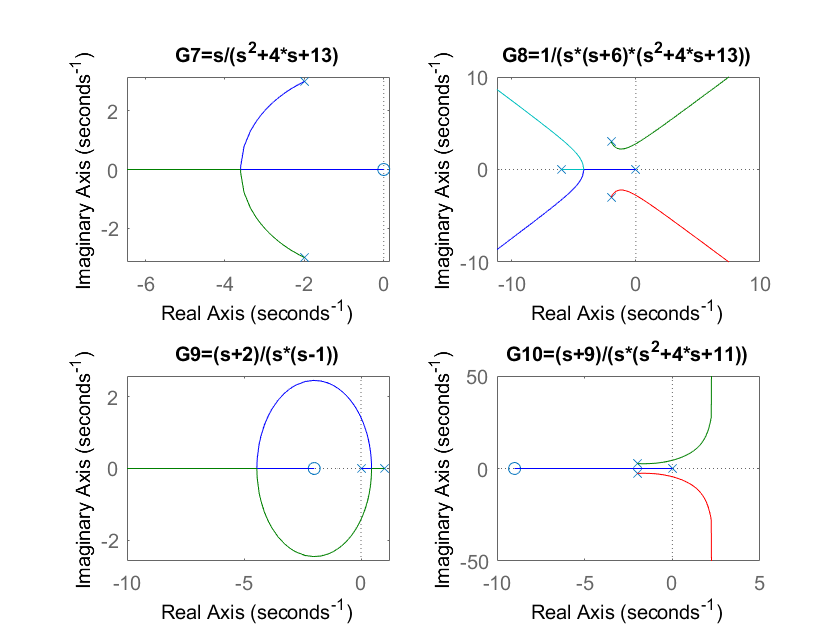

%% Some Example
G7=s/(s^2+4*s+13);
G8=1/(s*(s+6)*(s^2+4*s+13));
G9=(s+2)/(s*(s-1));
G10=(s+9)/(s*(s^2+4*s+11));
figure
subplot(2,2,1);
rlocus(G7);
title('G7=s/(s^2+4*s+13)');

subplot(2,2,2);
rlocus(G8);
title('G8=1/(s*(s+6)*(s^2+4*s+13))');

subplot(2,2,3);
rlocus(G9);
title('G9=(s+2)/(s*(s-1))');

subplot(2,2,4);
rlocus(G10);
title('G10=(s+9)/(s*(s^2+4*s+11))');



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%Practice
% s=tf('s');
% G1=1/(s*(s+3));
% G2=1/(s*(s^2+5*s+6));
% G3=(s+3)/(s^2-s-2);
% G4=(s+1)/(s^3+4*s^2+6*s+4);
% G5=(s^2+2*s+2)/(s*(s^4+9*s^3+33*s^2+51*s+26));
% G6=(s^2+2*s+2)/(s^2*(s^4+9*s^3+33*s^2+51*s+26));
%rlocus(G2)
%rlocus(G3)
%rlocus(G4)
%rlocus(G5)

# 6.4 Finding Parameters of Root Locus by Matlab

%In case we require to find value of K and their root on Root Locus
[r,k] = rlocus(GH);
%In case when we want to find value of roots for certain gain
k1=0.5

k1 = 0.5000

r1=rlocus(GH,k1)

r1 =    -9.4721
   -0.5279


# 6.5 Choosing a Value of K from Root Locus

## 6.5.1 When we have zeta and Natural Frequency

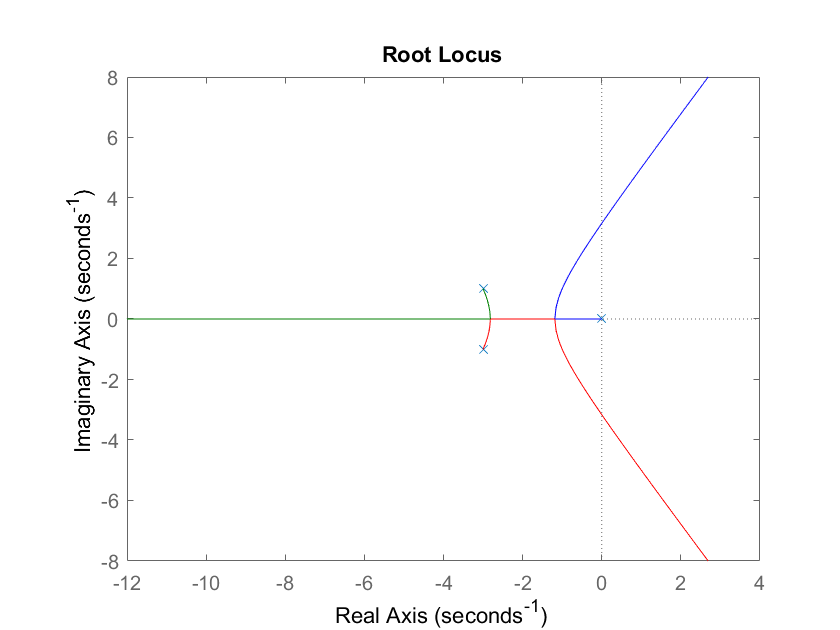

%Generate s-plane grid of constant damping factors and natural frequencies
% To get the desired area for certain requirements
GH=K/(s^3+6*s^2+10*s);
rlocus(GH);

On the plot below, the two dotted lines at about a 45-degree angle indicate pole locations with  $\xi$= 0.7; in between these lines, the poles will have  $\xi$> 0.7 and outside of these lines  $\xi$< 0.7.  The semicircle indicates pole locations with a natural frequency  $\omega_n$= 1.8; inside of the circle,  $\omega_n$< 1.8 and outside of the circle $\omega_n$ > 1.8. 

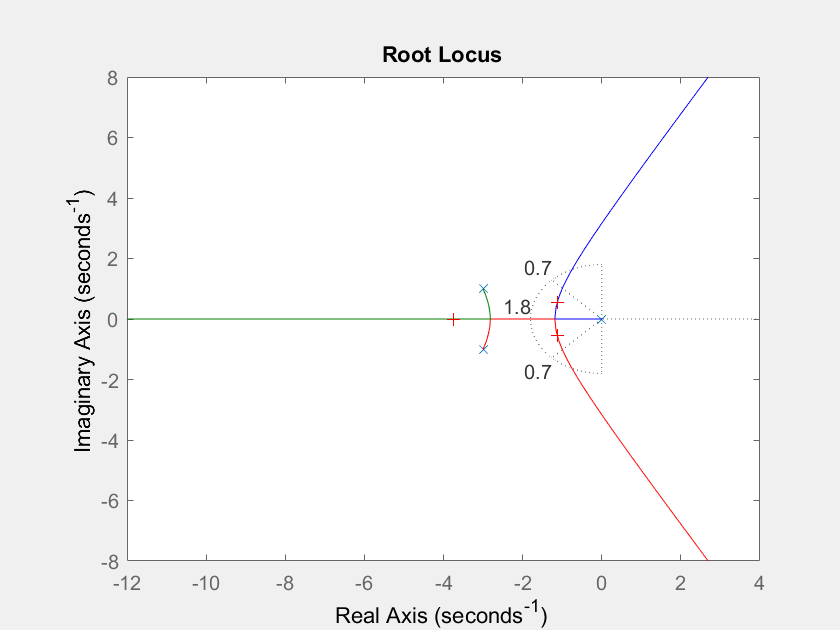

Select a point in the graphics window


selected_point = -1.1438 + 0.5455i

k = 0.5849

poles =   -3.7486 + 0.0000i
  -1.1257 + 0.5414i
  -1.1257 - 0.5414i


zeta = 0.7;
wn = 1.8;
sgrid(zeta,wn)

%To locate roots ans gain For your system
%Based on Requiement choose the location
[k,poles] = rlocfind(GH)

## 6.5.2 When we have zeta Only

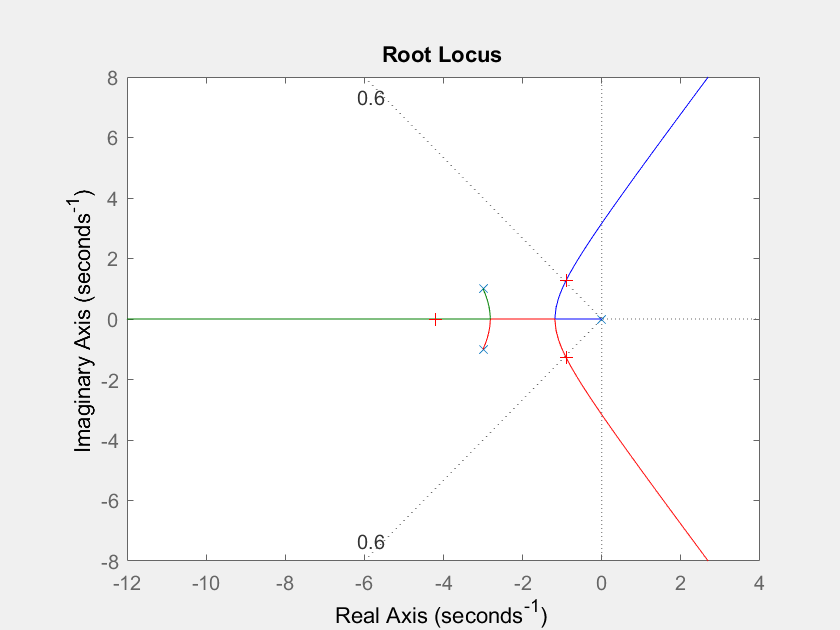

Select a point in the graphics window


selected_point = -0.9163 + 1.2727i

k = 1.0162

poles =   -4.1931 + 0.0000i
  -0.9035 + 1.2678i
  -0.9035 - 1.2678i


%Generate s-plane grid of constant damping factors and natural frequencies
% To get the desired area for certain requirements
GH=K/(s^3+6*s^2+10*s);
rlocus(GH);
zeta = 0.6;
wn = 0;         % Substitute Zero here
sgrid(zeta,wn)

%To locate roots ans gain For your system
%Based on Requiement choose the location
[k,poles] = rlocfind(GH)

# 6.6 Effect of Addition of Poles in Root Locus

Effects of addition of open loop poles can be summarized as :

- Root locus shifts towards imaginary axis. 

- System stability relatively decreases. 

- System becomes more oscillatory in nature. 

- Range of operating values of 'K' for stability of the system decreases. 

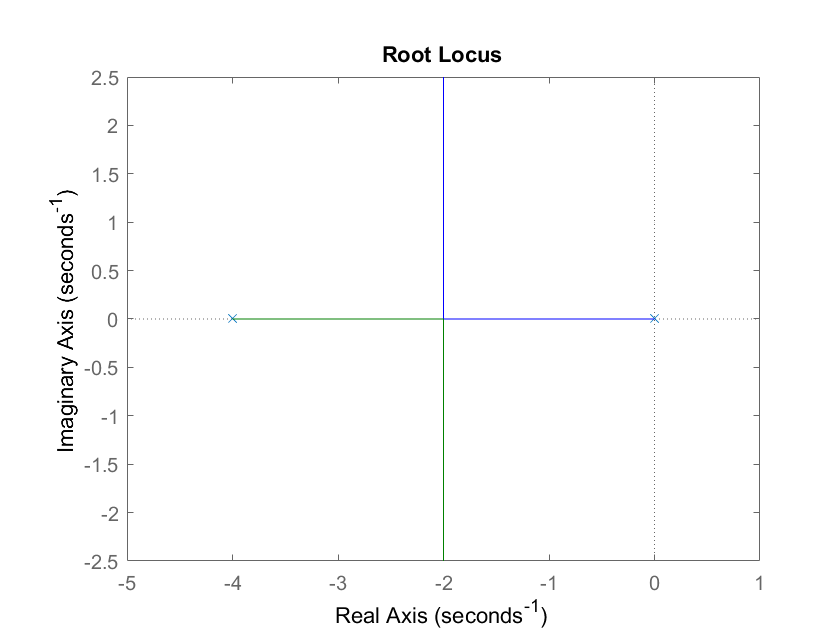

%A system with two poles
GH1=1/(s*(s+4));
rlocus(GH1);

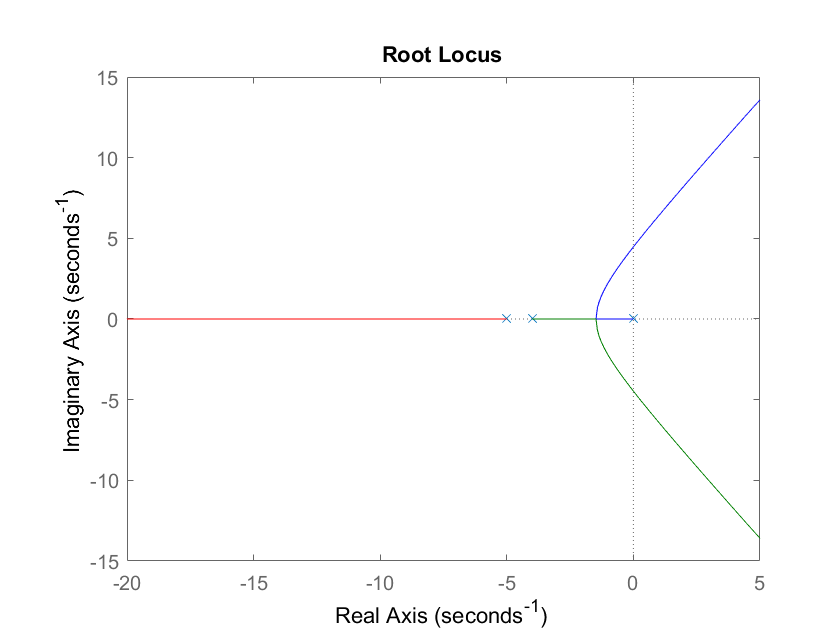

%Adding one more Poles
GH2=1/(s*(s+4)*(s+5));
rlocus(GH2);

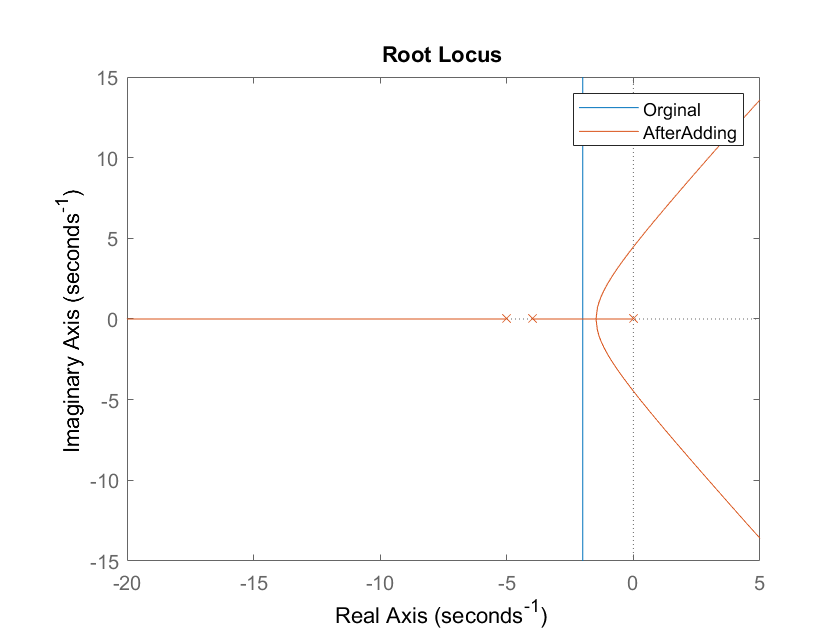

%Plotting Both in Combined Way
rlocus(GH1,GH2);
legend Orginal AfterAdding

# 6.7 Effect of Addition of Zeros in Root Locus

In short effect of addition of zeros are : 

- Root locus shifts to left away from imaginary axis. 

- Relative stability of the system increases. 

- System becomes less oscillatory. 

- Range of operating values of 'K' for system stability increases. 

%A system with three poles
GH1=1/(s*(s+4)*(s+5));
rlocus(GH1);

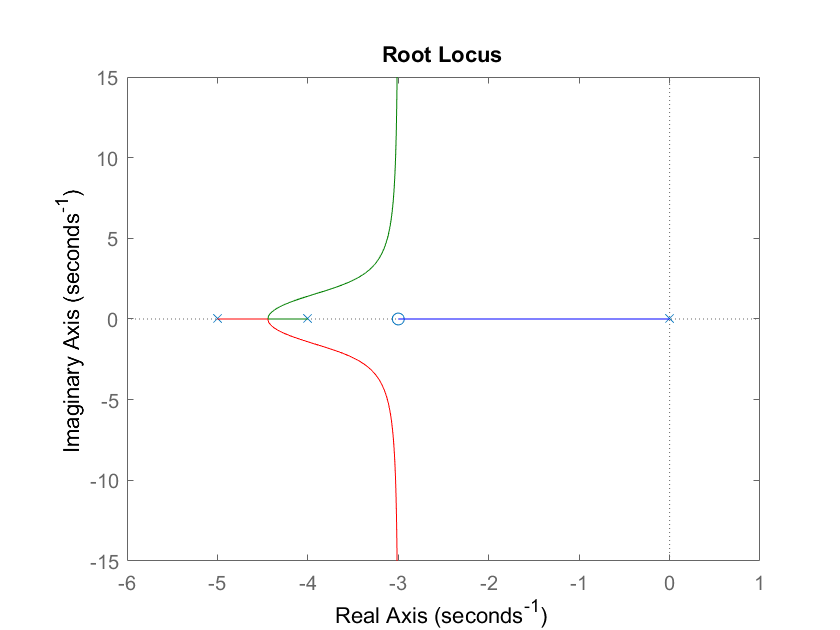

%Adding one Zero
GH2=(s+3)/(s*(s+5)*(s+4));
rlocus(GH2);

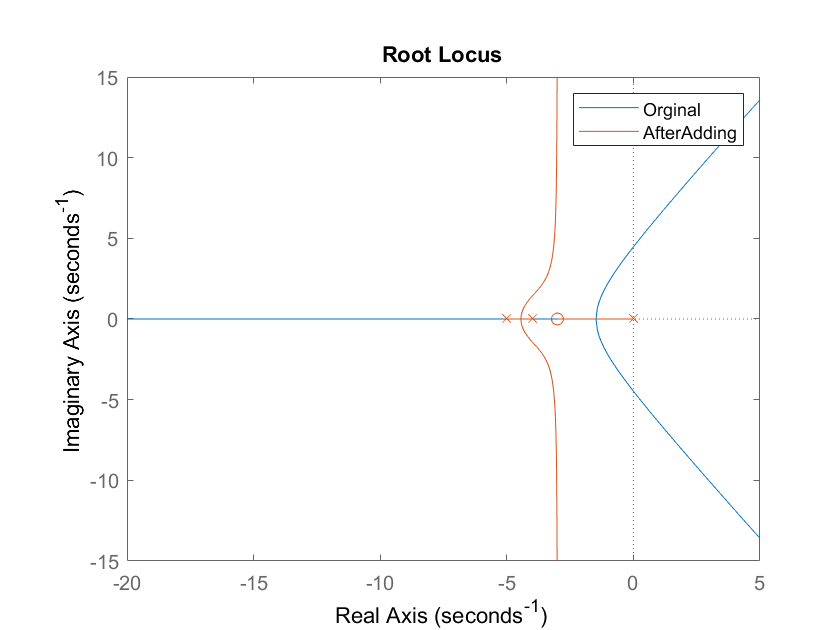

%Plotting Both in Combined Way
rlocus(GH1,GH2);
legend Orginal AfterAdding

# 6.8 Cancellation of Poles by Zeros


$$G\left(s\right)=\frac{K}{s\left(s+2\right)\left(s+4\right)}$$



$$H\left(s\right)=\left(s+2\right)$$



$$G\left(s\right)H\left(s\right)=K*\frac{\left(s+2\right)}{s\left(s+2\right)\left(s+4\right)}$$


G=K/(s*(s+2)*(s+4));
H=(s+2);
GH_yourself=K/(s*(s+4));
fprintf("The Combined Transfer Function by Yourself is");

The Combined Transfer Function by Yourself is

GH_yourself


GH_yourself =
 
     10
  ---------
  s^2 + 4 s
 
Continuous-time transfer function.



rlocus(GH_yourself);

GH=G*H;
fprintf("The COmbined Transfer Function is");

The COmbined Transfer Function is

GH


GH =
 
      10 s + 20
  -----------------
  s^3 + 6 s^2 + 8 s
 
Continuous-time transfer function.



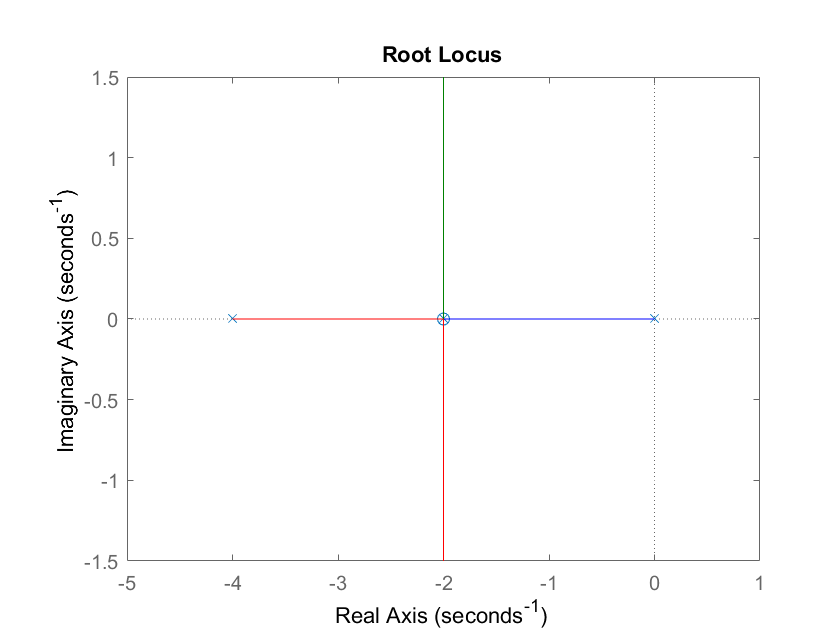

rlocus(GH);

# 6.9 Inverse Root Locus

**Root Locus is defined **as, the locus of the closed loop poles obtained when system gain 'K' is varied from -∞ to +∞ is called Root Locus. When 'K' is varied from -∞ to 0, the plot obtained is called **Inverse root locus. **

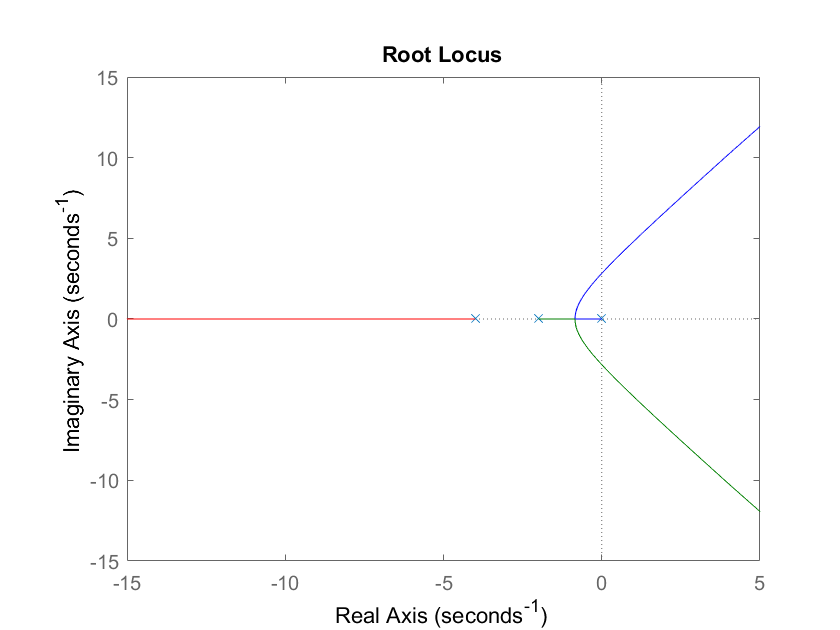

G=K/(s*(s+2)*(s+4));
H=1;
GH=G*H;
rlocus(GH);

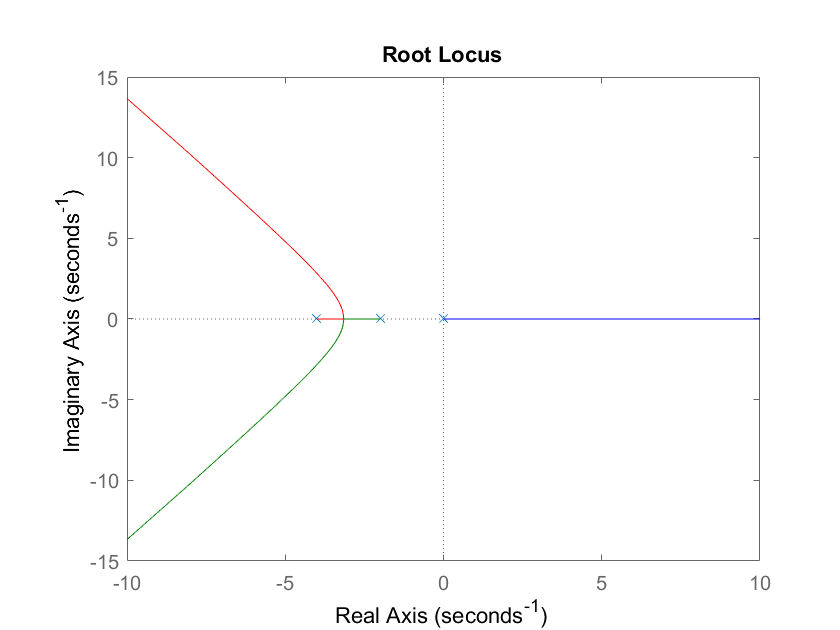

rlocus(-GH);    %Minus for Inverse Root Locus

# References

- Mathworks.inc

- Nise, Norman S. "Control system engineering, John Wiley & Sons." *Inc, New York*(2011).

- [https://ctms.engin.umich.edu/CTMS/index.php?aux=Home](https://ctms.engin.umich.edu/CTMS/index.php?aux=Home)

- Bakshi, Uday A., and Varsha U. Bakshi. *Control system engineering*. Technical Publications, 2020.